# Cubic vs. Linear Interpolation Methods

This demo was rewritten from the RegularizeData3D examples. This examples shows the difference between the linear and cubic interpolation methods.

clear; close all;

## Input points.

inputPoints =[
	1,  0.5, 0.5;
	1,    2,   1;
	1,  3.5, 0.5;
	3, 0.75, 0.5;
	3,  1.5,   1;
	3, 2.25, 0.5;
	3,    3,   1;
	3,    4, 0.5];

## Calculate surface with linear and cubic interpolation methods

% Change the spacing to test each axis or both axes. You get the same
% surface profile whether the spacing is 0.5 or 0.01 on either or both
% axes.
x = 0:0.2:4;
y = 0:0.2:4;

% Set the smoothness.  See the help for details about the
% smoothness setting.
smoothness = 0.003;

% Calculate surface using cubic interpolation
zCubic = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'cubic');
% Other equivalent calls
% zCubic = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'cubic',[]);
% zCubic = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'cubic', 'normal');

% Calculate surface using linear interpolation
zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness);
% Other equivalent calls. If you use [] for smoothness, interp, or solver,
% the default argument is used. See the help
% zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'linear');
% zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, []);
% zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, [], []);
% zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'linear', []);
% zLinear = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {x, y}, smoothness, 'linear', 'normal');

## Plots

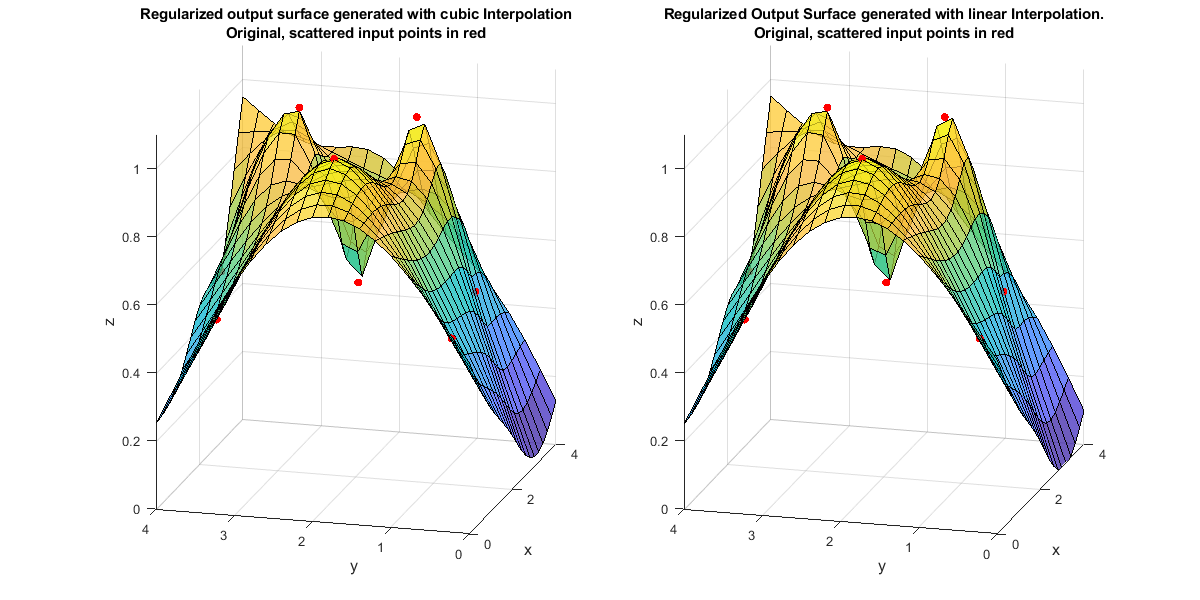

screenSize = get(groot, 'screenSize');
figurePosition = screenSize(3:4)*0.1;
figureSize = [1200 600];
figurePositionAndSize = [figurePosition figureSize];
figure('color', 'w', 'position', figurePositionAndSize)

% Plot this figure on the left.
subplot1 = subplot(1, 2, 1);
view(subplot1,[-74.5, 14]);
grid(subplot1, 'on');
hold(subplot1, 'all');

% Note that surf uses the meshgrid format for plotting surfaces using
% vectors for x and y. regularizeNd outputs in the ndgrid format. In 2d,
% meshgrid is the transpose of the ndgrid format.
surf(x, y, zCubic', 'facealpha', 0.75);
scatter3(inputPoints(:, 1), inputPoints(:, 2), inputPoints(:, 3),[], 'r', 'filled');

xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);
title(sprintf('Regularized output surface generated with cubic Interpolation\nOriginal, scattered input points in red'));
axis([0, 4, 0, 4, 0, 1.1]);


% Plot this figure on the right.
subplot2 = subplot(1, 2, 2);
view(subplot2,[-74.5, 14]);
grid(subplot2, 'on');
hold(subplot2, 'all');

% Note that surf uses the meshgrid format for plotting surfaces using
% vectors for x and y. regularizeNd outputs in the ndgrid format. In 2d,
% meshgrid is the transpose of the ndgrid format.
surf(x, y, zLinear', 'facealpha', 0.75);
scatter3(inputPoints(:, 1), inputPoints(:, 2), inputPoints(:, 3), [], 'r', 'filled');

xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);
title(sprintf('Regularized Output Surface generated with linear Interpolation.\nOriginal, scattered input points in red'));
axis([0, 4, 0, 4, 0, 1.1]);